# Introduction to Image Stitching

Stitching images together to create a larger panoramic image is a common task. Work through this reading to see an example with just two images. Several new functions are described here that you'll use to stitch together multiple images, including in your final project!

## Import and View the Images

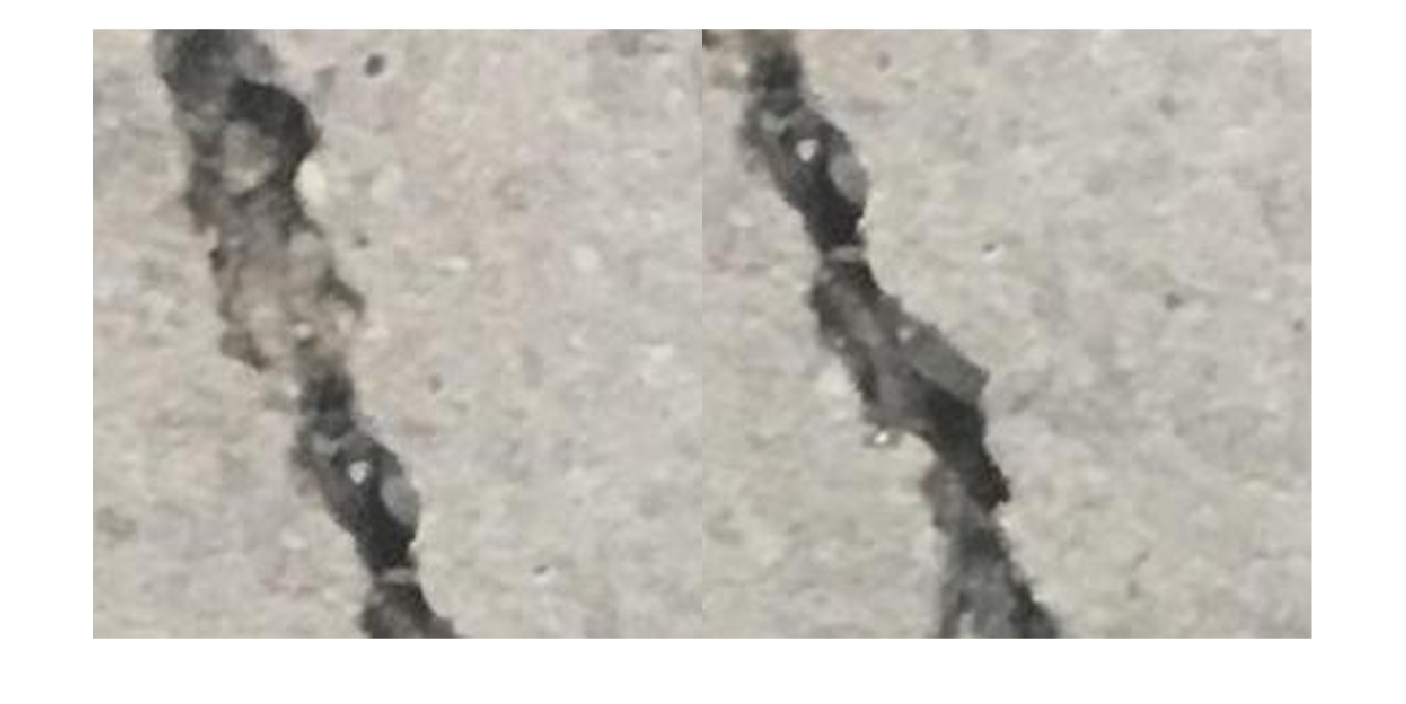

movingImg = imread("00475.jpg");
fixedImg = imread("00476.jpg");
montage({movingImg,fixedImg})

## Register the Two Images

The function `registerConcreteImages` was created using the Registration Estimator App. It uses SURF features and a rigid transformation to register the two images. There are a few key tasks to this step:

- Register the images

- Extract the geometric transformation for the moving image

- Create a default rigid transformation for the fixed image

You need the identity transformation to place the fixed image into the correct location of the final panorama image without warping. 

Run this section to register the images, view the matched feature locations, and create the geometric transformations. 

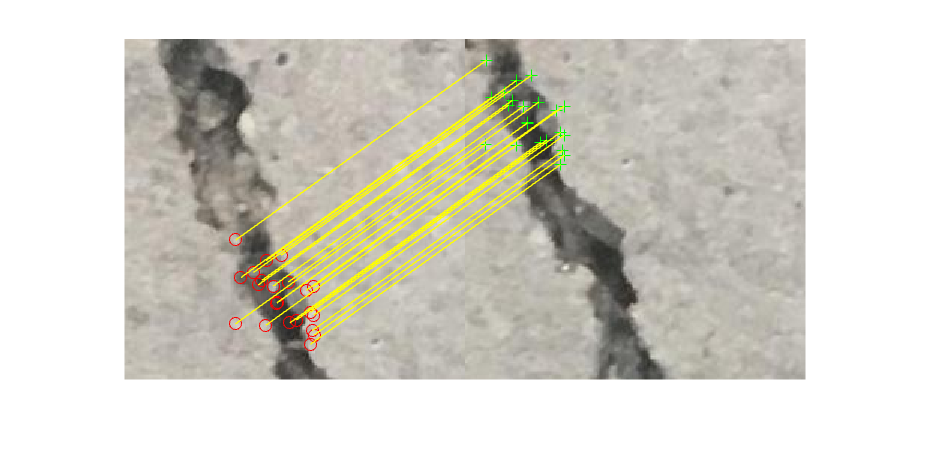

regOutput = registerConcrete(movingImg,fixedImg);

showMatchedFeatures(movingImg,fixedImg,regOutput.MovingMatchedFeatures,...
        regOutput.FixedMatchedFeatures,"montage");

movingT = regOutput.Transformation;
fixedT = rigidtform2d();

## Initialize the Template

Pixel locations for individual images are referenced using row and column indices. To stitch the images together, you need to know where the pixels belong in the "world coordinate" system. This is not a calibrated coordinate system but is relative to the images being stitched together. The upper-left corner of the fixed image serves as the anchor point to which all other pixel locations are referenced.

### Find the image world coordinates

To find the new coordinates, use the `outputLimits `function. This function uses the geometric transformation to translate the image row and column indices into the world coordinate system.

Run this section to determine how the images are positioned relative to each other. 

Notice that the moving image extends into the negative x and y directions. This means the image position is shifted left and up relative to the fixed image. The fixed image starts at `[x y] = [1 1]` and ends at coordinates based on the image size.

% Get the image size. Both images are the same size
[nrows, ncols, ~] = size(movingImg);
[xlimMoving, ylimMoving] = outputLimits(movingT,[1 ncols],[1 nrows])

xlimMoving = 1×2 single row vector
  -58.9747  166.8918


ylimMoving = 1×2 single row vector
 -118.8585  107.0080


[xlimFixed, ylimFixed] = outputLimits(fixedT,[1 ncols],[1 nrows])

xlimFixed =      1   227


ylimFixed =      1   227


### Initialize the panorama template

Use the world coordinate information to initialize the size of the panorama image. In general, you need to find the min and max `xlim` value and min and max `ylim` value.

Run this section to create an empty panorama image. Note that the the crack images are color.

% Find the smallest and largest extents in the world coordinate system
xMin = min([xlimMoving, xlimFixed]);
xMax = max([xlimMoving, xlimFixed]);
yMin = min([ylimMoving, ylimFixed]);
yMax = max([ylimMoving, ylimFixed]);

Use these values to find the size of the final panorama image

% Width and height of panorama.
w  = round(xMax - xMin);
h = round(yMax - yMin);

% Initialize the empty panorama. This is a color image.
panorama = zeros([h, w, 3],"uint8");

## Create the Panorama

In this step, you warp the two images with their geometric transformation and place them in the panorama. 

### Create an Alpha Blender object

You combine the images using the `vision.AlphaBlender` object. This object is especially useful when you have several images, as it maintains a record of added images and their locations. 

Run this section to create the `AlphaBlender` object.

blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port")

blender =   vision.AlphaBlender with properties:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]


Here, you use `vision.AlphaBlender `with the `"Binary Mask" `operation so the pixel intensities in the final image are determined by a mask you provide.  The `"MaskSource"` option is set to `"Input port",` meaning you will provide the mask as an input argument. 

### Create the spatial referencing object

You need to warp the images and put them in the correct place in the final panorama. This requires mapping the warped image pixel locations to the final positions in the panorama. To do this, create a spatial referencing object with the `im2ref` function. 

Run this section to create a spatial referencing object that maps the world coordinates to pixel locations of the final panorama.

panoramaView = imref2d([h w],[xMin xMax],[yMin yMax])

panoramaView =   imref2d with properties:

           XWorldLimits: [-58.9747 227]
           YWorldLimits: [-118.8585 227]
              ImageSize: [346 286]
    PixelExtentInWorldX: 0.9999
    PixelExtentInWorldY: 0.9996
    ImageExtentInWorldX: 285.9747
    ImageExtentInWorldY: 345.8585
       XIntrinsicLimits: [0.5000 286.5000]
       YIntrinsicLimits: [0.5000 346.5000]


### Warp the images

Warp each image, including the fixed image. Even though the fixed image geometric transformation is the identity, using the spatial referencing object places the fixed image into the correct location of the larger panorama.

Run this section to warp the images and view the results.

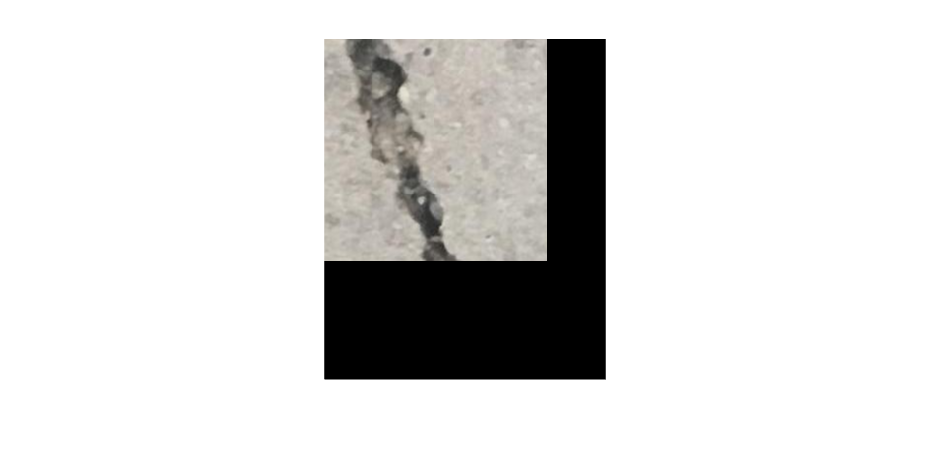

movingWarped = imwarp(movingImg,movingT,"OutputView",panoramaView);
fixedWarped = imwarp(fixedImg,fixedT,"OutputView",panoramaView);
imshow(movingWarped)

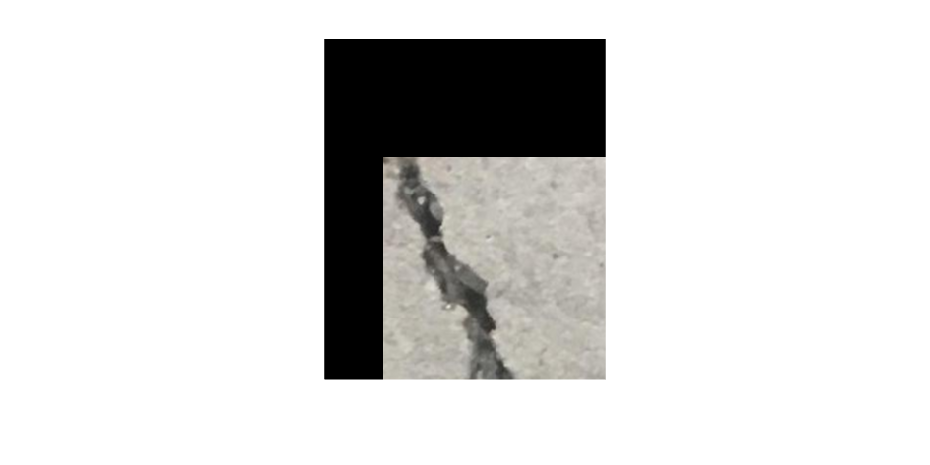

imshow(fixedWarped)

### Place the warped images into the panorama

You now have two warped images that need to be blended together using the alpha blender object. Add each to the panorama using the alpha blender object. For each warped image, create a corresponding mask to specify which pixel panorama should be updated when blending the images together.

Run this section to create the final panoramic image.

mask = ones(nrows, ncols, "logical");
fixedMask = imwarp(mask, fixedT, "OutputView", panoramaView);
movingMask = imwarp(mask, movingT, "OutputView", panoramaView);

Put the images together with your alpha blender object. In addition to the syntax below you will sometimes see the syntax 

`step(blender, panorama, img, mask)`

The two syntaxes are equivalent. 

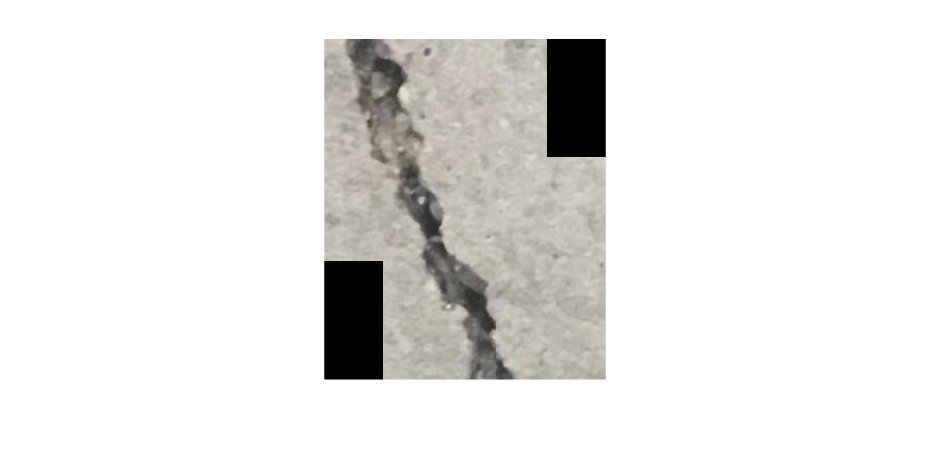

% Add the first image to the panorama
panorama = blender(panorama,movingWarped,movingMask);
% Add the second image
panorama = blender(panorama,fixedWarped,fixedMask);
imshow(panorama)

## Stitching Together More Than Two Images

With just two images, either could be the fixed image. If you have three or more images and are using an affine or projective transformation, you will typically want to choose an image near the center to be the fixed image. No matter your fixed image, you'll need to take care to create transformations that define how all moving images are shifted with respect to the fixed image. You'll see how to do this in the next video.

*Copyright 2022 The MathWorks, Inc.*